Calculates EOD amplitude statistics for the Brasil *Eigenmannia* data.

The values are in **Ampere-meters**.

This is **FIGURE 3B** of the Cave Manuscript.

% Data are found in these files - load them before running this script
% load CaveDataRev2018a.mat
% load SurfaceDataRev2018a.mat

## Setup


% Set the number of bins for the histogram here:

    numbins = 20;
    
    ctrs = 0:0.003/numbins:0.003;
    
% There are Contaminated / Bad amplitude readings in surface data
% srf(1).fish(12), srf(2).fish(20), srf(3).fish(31), 
% srf(4).fish(22), srf(5).fish(4), srf(5).fish(23)

% These are the indices to skip for the surface data
BadIDXs = [12,32,64,86,90,109];


## Extract the electric field strength values for the fish


CaveAmps = []; SurfaceAmps = []; 

% For each surface entry (N=5)
for j=1:length(srf) 
    % For each fish in the entry
    for k=1:length(srf(j).fish) 
        SurfaceAmps(end+1) = srf(j).fish(k).dipStrength; 
    end
end

% For each cave entry (N=14)
for j=1:length(cave)
    % For each fish in the entry
    for k=1:length(cave(j).fish)
        CaveAmps(end+1) = cave(j).fish(k).dipStrength; 
    end
end

% The list of GoodIDXs removes the bad indices. Terrible coding.
GoodIDXs = setdiff(1:length(SurfaceAmps), BadIDXs);


## Calculate the statistics for surface and cavefish

    meanSurfaceAmp = mean(SurfaceAmps(GoodIDXs));
    meanCaveAmp = mean(CaveAmps);
    medianSurfaceAmp = median(SurfaceAmps(GoodIDXs));
    medianCaveAmp = median(CaveAmps);
    stdSurfaceAmp = std(SurfaceAmps(GoodIDXs));
    stdCaveAmp = std(CaveAmps);    
fprintf('SURFACE was %i recordings. \n', length(srf));

SURFACE was 5 recordings. 


fprintf('SURFACE MeanEODAmp = %1.6f, MedianEODAmp = %1.6f, N = %i \n', meanSurfaceAmp, medianSurfaceAmp, length(SurfaceAmps));

SURFACE MeanEODAmp = 0.000650, MedianEODAmp = 0.000470, N = 110 


fprintf('CAVE was %i recordings. \n', length(cave));

CAVE was 14 recordings. 


fprintf('CAVE MeanEODAmp = %1.6f, MedianEODAmp = %1.6f, N = %i \n', meanCaveAmp, medianCaveAmp, length(CaveAmps));

CAVE MeanEODAmp = 0.000966, MedianEODAmp = 0.000609, N = 82 



[P,H,STATS] = ranksum(CaveAmps, SurfaceAmps(GoodIDXs));    
    fprintf('Wilcoxon RankSum: Surface vs Cave EOD Amps? pVal = %1.4f, Z = %1.4f \n', P, STATS.zval);

Wilcoxon RankSum: Surface vs Cave EOD Amps? pVal = 0.0029, Z = 2.9777 


    
% [stts.H, stts.P, stts.CI, stts.STATS] = ttest2(CaveAmps, SurfaceAmps(GoodIDXs), 'vartype', 'unequal');
% 
%     fprintf('ttest2 cave and surface? pVal = %1.5f, CI = %1.5f %1.5f \n', stts.P, stts.CI(1), stts.CI(2));
%     stts.STATS
%     fprintf('Cave mean & std ampere-centimeters %1.6f %1.6f \n', stts.meanCaveAmp, stts.stdCaveAmp);
%     fprintf('Surface mean & std ampere-centimeters %1.6f %1.6f \n', stts.meanSurfaceAmp, stts.stdSurfaceAmp);    

## Plot the amplitude data for the manuscript

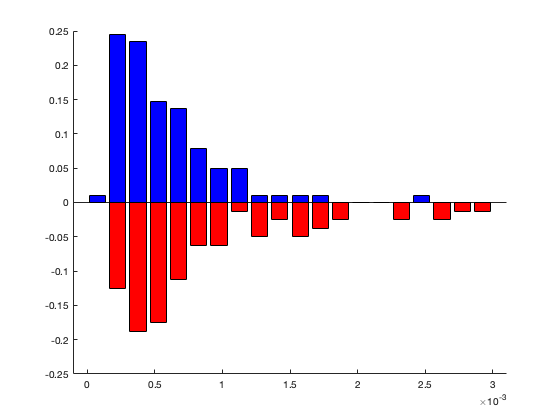

    
    surfhist = histcounts(SurfaceAmps(GoodIDXs), ctrs);
        surfhist = surfhist / sum(surfhist);
    cavehist = histcounts(CaveAmps, ctrs);
        cavehist = cavehist / sum(cavehist);        
    plotspots = ctrs(2:end) - 0.003/(2*numbins);

% figure(1); clf; hold on; % NOT USED IN MANUSCRIPT
%     histogram(SurfaceAmps(GoodIDXs), ctrs, 'FaceColor', '[0 0.5 1]');
%     histogram(CaveAmps, ctrs, 'FaceColor', '[1 0 0]'); 
%     xlim([0 0.0022]);
% 
    
% figure(2); clf; hold on; % NOT USED IN MANUSCRIPT
    % plot(plotspots, surfhist, 'Color', '[0 0.5 1]', "LineWidth", 2);
    % plot(plotspots, cavehist, 'Color', '[1 0 0]', "LineWidth", 2);
    
figure(3); clf; hold on; % FIGURE USED IN MANUSCRIPT
    bar(plotspots, surfhist, 'b');
    bar(plotspots, -cavehist, 'r');
    ylim([-0.25, 0.25]);

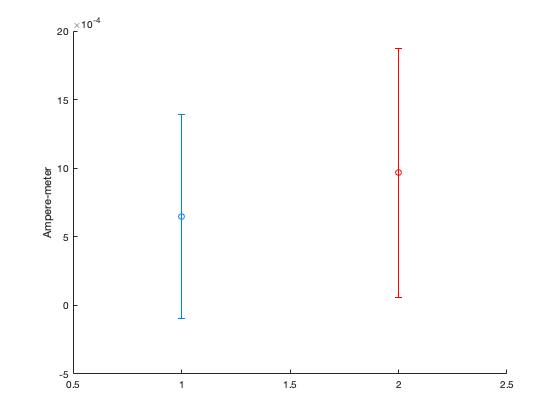

    
figure(4); clf; hold on; % NOT USED IN MANUSCRIPT
    plot(1,meanSurfaceAmp, 'o', 'Color', '[0 0.5 1]');
        errorbar(1, meanSurfaceAmp, stdSurfaceAmp, "both", 'Color', '[0 0.5 1]')
    plot(2,meanCaveAmp, 'o', 'Color', '[1 0 0]')
        errorbar(2, meanCaveAmp, stdCaveAmp, "both", 'Color', '[1 0 0]')
    xlim([0.5 2.5])
    ylabel('Ampere-meter');